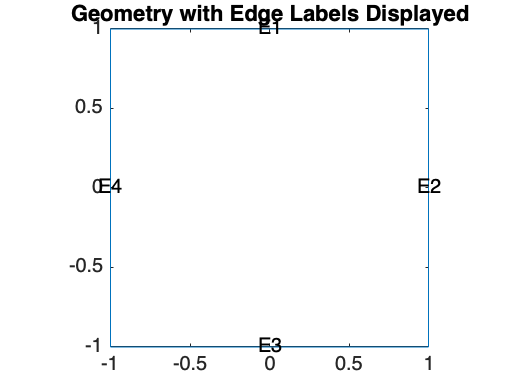

%using MATLAB's PDE solver to model the simple situation
%create PDE model
numberOfPDE = 1;
model = createpde(numberOfPDE);

%define coefficients
c0 = 1; %speed of sound in water
%NOTE: currently doesn't work with c0 = 1500 m/s
%causes problems with memory, not sure about a work-around
%this could be using another method or keeping it dimensionless during PDE
%solving and applying dimensions to the result
m = 1;
c = c0^2;
f = 0;
a = 0;

%create geometry
%using predefined squareg for a square
geometryFromEdges(model,@squareg);
figure;
pdegplot(model,"EdgeLabels","on"); %!don't forget the g in the function!!!
axis equal
title("Geometry with Edge Labels Displayed")

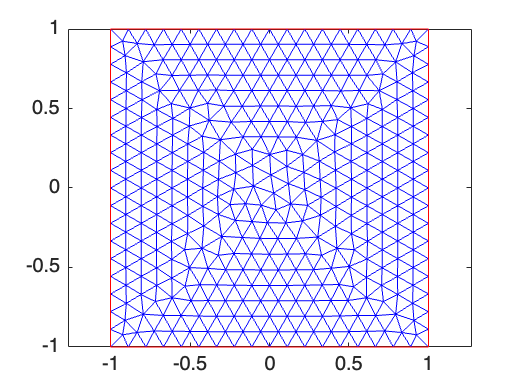

%ylim([0,1])

%apply boundary conditions
%neumann boundary on outer edges for perfect reflection
%bOuter = applyBoundaryCondition(model,"neumann","Edge",(1:4),"g");
%applyBoundaryCondition(model,"dirichlet","Edge",(1:3),"u",1);
applyBoundaryCondition(model,"dirichlet","Edge",[2,4],"u",0);
applyBoundaryCondition(model,"neumann","Edge",([1 3]),"g",0);
%specify coefficients
specifyCoefficients(model,"m",m,"d",0,"c",c,"a",a,"f",f);

%apply initial condition of 0 pressure
%setInitialConditions(model,1);
%setInitialConditions(model,0);
%setInitialConditions(model,5,"Edge",4)
u0 = @(location) atan(cos(pi/2*location.x));
ut0 = @(location) 3*sin(pi*location.x).*exp(sin(pi/2*location.y));
setInitialConditions(model,u0,ut0);

%generate mesh
generateMesh(model);
%plot the mesh
figure
pdemesh(model);
axis equal


%solve pde over time in tlist
n=20;
tlist = 0:n;
model.SolverOptions.ReportStatistics ='on';
result = solvepde(model,tlist);

1768 successful steps
137 failed attempts
3812 function evaluations
1 partial derivatives
409 LU decompositions
3811 solutions of linear systems


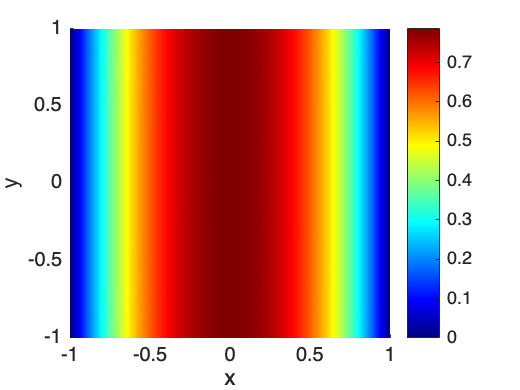

u = result.NodalSolution;
figure
pdeplot(model, "XYData",real(u),"Mesh","off");
colormap(jet)
xlabel("x")
ylabel("y")

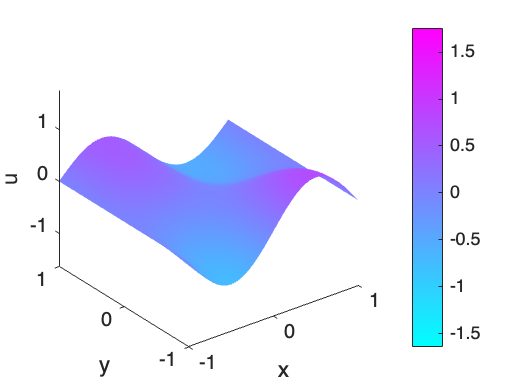

%title("Real Value Solution of Helmholtz Equation")
figure
umax = max(max(u));
umin = min(min(u));
for i = 1:n
    pdeplot(model,"XYData",u(:,i),"ZData",u(:,i), ...
                  "ZStyle","continuous","Mesh","off");
    axis([-1 1 -1 1 umin umax]); 
    caxis([umin umax]);
    xlabel x
    ylabel y
    zlabel u
    M(i) = getframe;
end